# MAE 342 Final Project ADCS/GNC Graphics

Richard Zhu

emdist = 384400e3; % earth-moon avg dist in m, NASA
[X, Y] = meshgrid(0:emdist/30:emdist, 0:emdist/30:emdist);
mue = 6.67e-11 * 5.972e24; % gravitational constant of Earth
mum = 6.67e-11 * 7.348e22; % gravitational constant of moon
mus = 6.67e-11 * 1.989e30; % gravitational constant of Sun
ms = 1121; % mass of satellite (kg)
re = 6378e3; % radius of Earth (m)

fx

fx = 	1.0e+03 *

    0.0000   -2.7197   -0.6799   -0.3021   -0.1699   -0.1087   -0.0755   -0.0554   -0.0424   -0.0335   -0.0271   -0.0224   -0.0188   -0.0160   -0.0137   -0.0119   -0.0105   -0.0092   -0.0082   -0.0073   -0.0065   -0.0058   -0.0051   -0.0045   -0.0038   -0.0030   -0.0019   -0.0000    0.0049    0.0302       NaN
    0.0000   -0.9615   -0.4865   -0.2580   -0.1552   -0.1025   -0.0724   -0.0538   -0.0415   -0.0329   -0.0267   -0.0221   -0.0186   -0.0158   -0.0136   -0.0119   -0.0104   -0.0092   -0.0081   -0.0072   -0.0064   -0.0057   -0.0051   -0.0045   -0.0038   -0.0031   -0.0021   -0.0005    0.0025    0.0086   -0.0030
    0.0000   -0.2432   -0.2404   -0.1740   -0.1216   -0.0870   -0.0644   -0.0493   -0.0387   -0.0312   -0.0256   -0.0213   -0.0180   -0.0154   -0.0133   -0.0116   -0.0102   -0.0090   -0.0080   -0.0071   -0.0064   -0.0057   -0.0051   -0.0045   -0.0039   -0.0032   -0.0025   -0.0016   -0.0005   -0.0002   -0.0030
    0.0000   -0.0860   -0.1160   -0.1068   -0.0870

**SRP**

s = 0:0.01:2; % reflectivity, 0 is transparent, 1 is fully absorptive, 2 is reflective
A_m = (0.00195:0.0001:0.005)'; % A/m, m^2/kg
P_s = 4.7e-6; % solar flux / speed of light (N/m2)
a_r = 1; % ratio of sun-earth dist to sun-satellite dist

1.5*0.00195*P_s*a_r*ms*1.575/4 % m/s^2

ans = 6.0681e-06

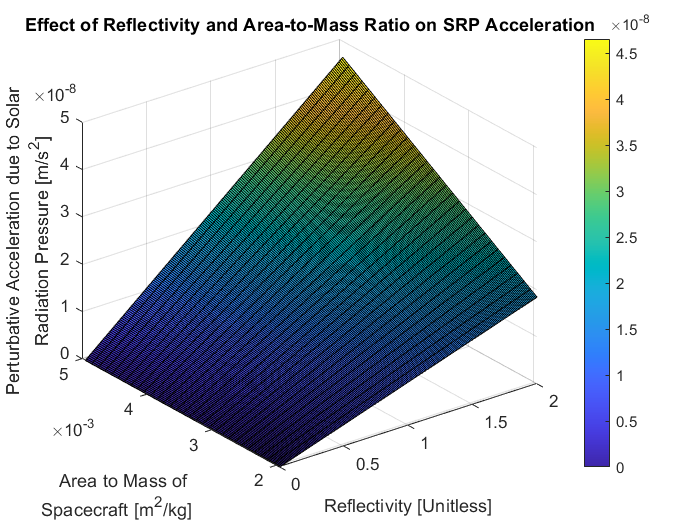


[S, A_M] = meshgrid(s, A_m);
f_srp1 = s.*A_m*P_s*a_r;
F_srp1 = griddata(S,A_M,f_srp1,S,A_M);
surf(S,A_M,F_srp1)
colorbar
title("Effect of Reflectivity and Area-to-Mass Ratio on SRP Acceleration")
xlabel("Reflectivity [Unitless]")
ylabel({"Area to Mass of "; "Spacecraft [m^2/kg]"})
zlabel({"Perturbative Acceleration due to Solar";"Radiation Pressure [m/s^2]"})

**Gravity Gradient**

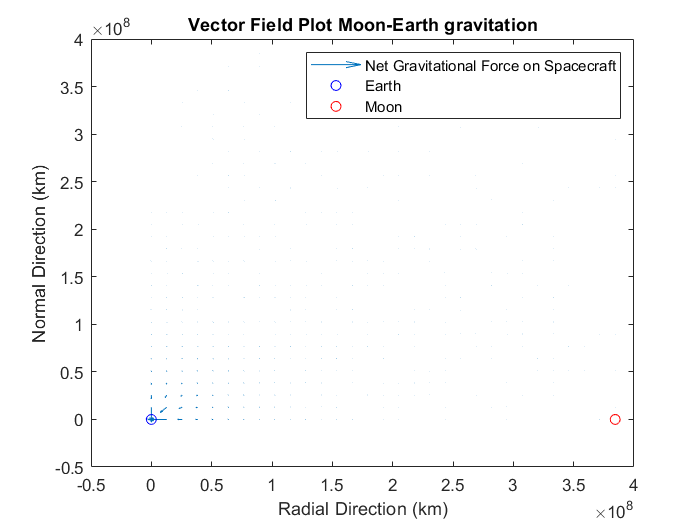

% gravitational force from Earth
R = (X.^2 + Y.^2).^0.5; % radial distance from Earth to each point
R(1,1) = Inf; % gravitational force undefined at center of earth
fx =  -mue * ms * X ./ R.^3; % total force in radial dir
fy = -mue * ms * Y ./ R.^3; % total force in normal dir


% gravitational force from Moon
R = ((X-emdist).^2 + Y.^2).^0.5; % radial distance from Moon to each point
fx = fx + mum*ms*(emdist-X)./R.^3;
fy = fy - mum*ms*Y./R.^3;


% taking log of data

fx(isinf(fx)) = 0;
fy(isinf(fy)) = 0;
quiver(X, Y, fx, fy);
hold on
title("Vector Field Plot Moon-Earth gravitation")
xlabel("Radial Direction (km)")
ylabel("Normal Direction (km)")
plot(0, 0, 'bo')
plot(emdist, 0, 'ro')
legend('Net Gravitational Force on Spacecraft', 'Earth', 'Moon')
% insert images into graph
hold off

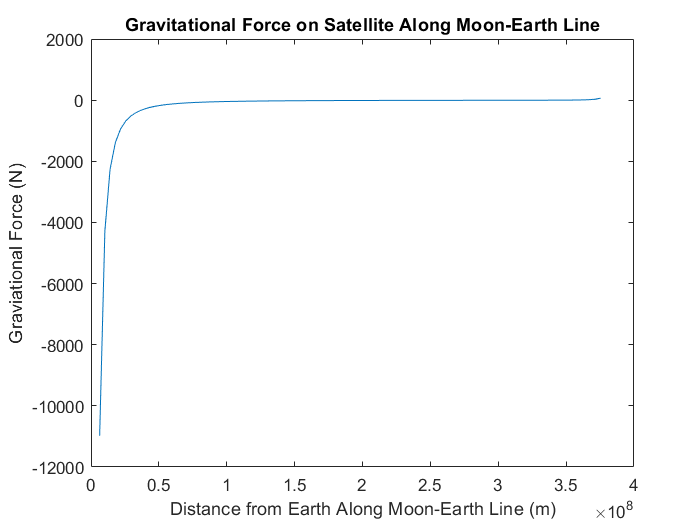

r = re:emdist/100:emdist-re;
plot(r, - mue*ms./r.^2 + mum*ms./(emdist-r).^2)
title("Gravitational Force on Satellite Along Moon-Earth Line")
xlabel("Distance from Earth Along Moon-Earth Line (m)")
ylabel("Graviational Force (N)")